# サッカーにおける攻撃力・守備力モデル

clear;clc;close all;

Jリーグの試合データの読み込み

tbl_results=readtable('../data/JLeagueResults.xlsx');
tbl_results.Category=categorical(tbl_results.Category);
tbl_results.HomeE=categorical(tbl_results.HomeE);
tbl_results.AwayE=categorical(tbl_results.AwayE);

ここ5年程度のJ1リーグのみ抽出

ind = tbl_results.Year<=2023 & tbl_results.Year>=2019 ...
    & tbl_results.Category=='Ｊ１';
tbl_results=tbl_results(ind,:);
seasonStartYearVals=unique(tbl_results.Year);

予測性能を保存する変数を用意する

PredictedMatches=[];    %予測対象の試合数
CorrectsByMassey=[];    %Masseyで予測した予測正解数

計算を早くするため，チーム名などを数値に変換しておく

matchData=zeros(size(tbl_results,1),4);
teamNames=unique([tbl_results.HomeE;tbl_results.AwayE]);
for n1=1:size(tbl_results,1)
    TeamAName=tbl_results.HomeE(n1);
    TeamBName=tbl_results.AwayE(n1);
    TeamANum=find(teamNames== TeamAName);
    TeamBNum=find(teamNames== TeamBName);
    matchData(n1,1)=TeamANum;
    matchData(n1,2)=TeamBNum;
    matchData(n1,3)=tbl_results.HomeGoals(n1);
    matchData(n1,4)=tbl_results.AwayGoals(n1);
end

### レーティングを計算する

- シーズンが変わった時に初期化する

- 日付が変わったらレーティングを計算する

- 予測対象試合でなくても計算しておく(予測対象試合は後で抽出しなおす)

RatingValus=zeros(size(matchData,1),4);
tbl_results=sortrows(tbl_results,"Date");


for n1=1:size(tbl_results,1)
    if n1>1 && ...
            (tbl_results.Year(n1)>tbl_results.Year(n1-1))
        r_O=ones(size(teamNames));     %攻撃力レーティング
        r_D=ones(size(teamNames));     %守備力レーティング
        r_homeAdv=0.1;
    end

    if n1>1 && ...
            (tbl_results.Date(n1)>tbl_results.Date(n1-1))

        ind = (tbl_results.Year==tbl_results.Year(n1)) ...
            & tbl_results.Date< tbl_results.Date(n1);
        tmpMatchData=matchData(ind,:);


勾配法による最適化

        for k=1:100
            for k2=1:randperm(size(tmpMatchData,1))
                TeamANum=tmpMatchData(k2,1);
                TeamBNum=tmpMatchData(k2,2);
                s_i=matchData(k2,3);
                s_i_hat=(r_O(TeamANum)+r_homeAdv)*r_D(TeamBNum);
                s_j=matchData(k2,4);
                s_j_hat=r_O(TeamBNum)*r_D(TeamANum);

                r_O(TeamANum)=r_O(TeamANum) ...
                    -K*( ...
                    (r_O(TeamANum)+r_homeAdv)*r_D(TeamBNum)^2 ...
                    -s_i*r_D(TeamBNum) ...
                    );
                
                r_D(TeamANum)=r_D(TeamANum) ...
                    -K*( ...
                    -s_j*r_O(TeamBNum)+r_O(TeamBNum)^2*r_D(TeamANum) ...
                    );
                
                r_O(TeamBNum)=r_O(TeamBNum) ...
                    -K*( ...
                    -s_j*r_D(TeamANum)+r_D(TeamANum)^2*r_O(TeamBNum) ...
                    );
                
                r_D(TeamBNum)=r_D(TeamBNum) ...
                    -K*( ...
                    (r_O(TeamANum)+r_homeAdv)^2*r_D(TeamBNum) ...
                    -s_i*(r_O(TeamANum)+r_homeAdv) ...
                    );

seasonStartYearVal = 2019

seasonStartYearVal = 2020

seasonStartYearVal = 2021

seasonStartYearVal = 2022

seasonStartYearVal = 2023

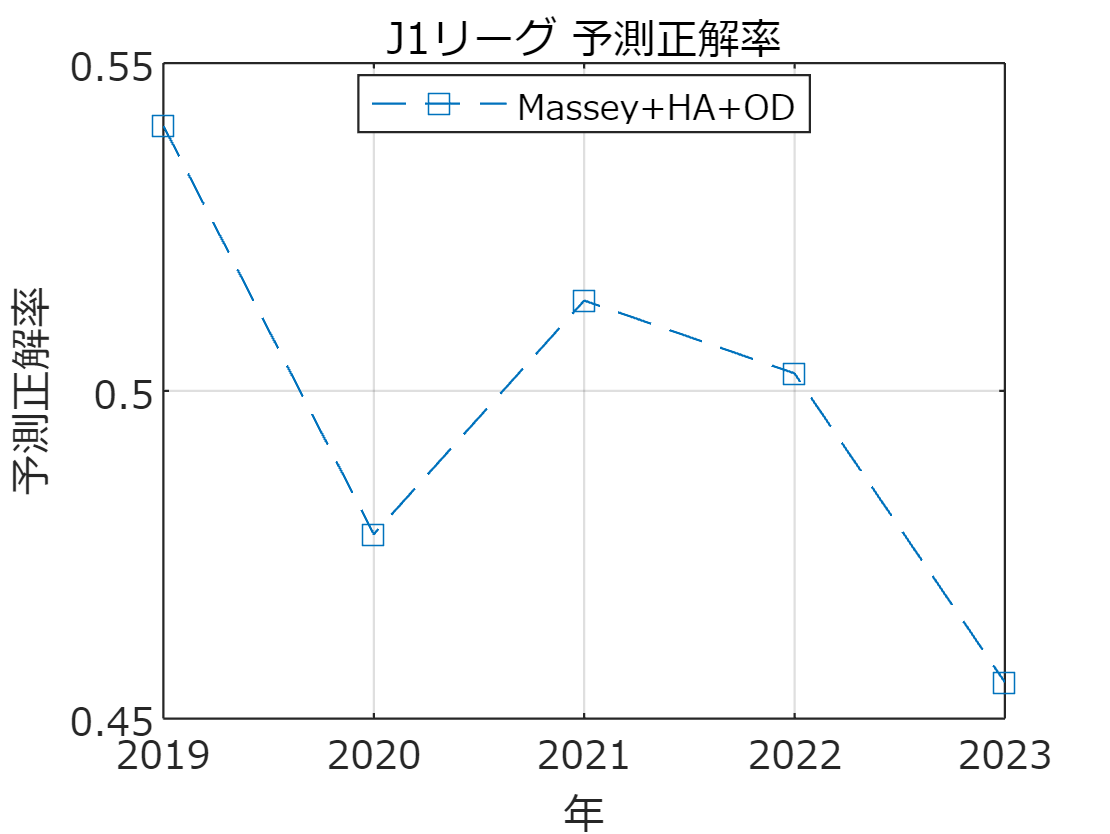

                r_homeAdv=r_homeAdv ...
                    -K*( ...
                    (r_O(TeamANum)+r_homeAdv)*r_D(TeamBNum)^2 ...
                    -s_i*r_D(TeamBNum) ...
                    );

                r_O=max(r_O,0);
                r_D=min(r_D,1);
                r_homeAdv=max(r_homeAdv,0);
            end
        end

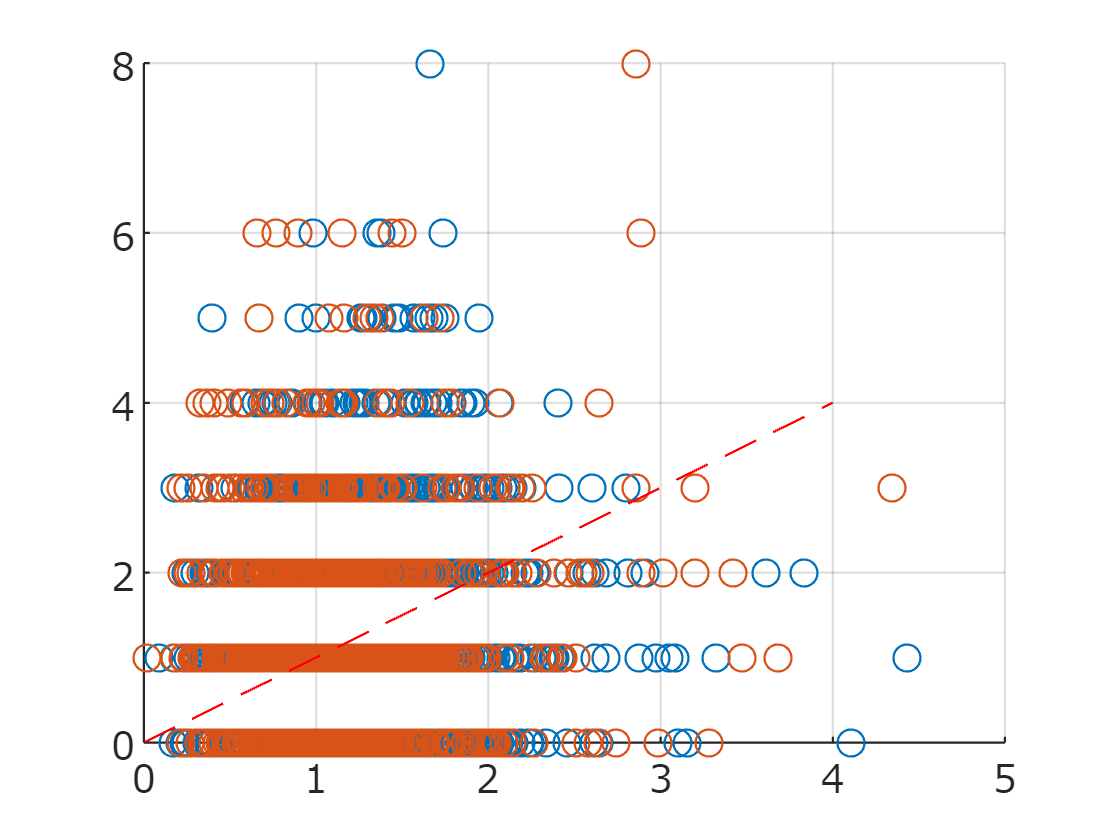


    end

    TeamANum=matchData(n1,1);
    TeamBNum=matchData(n1,2);


    RatingValus(n1,:) ...
        =[r_O(TeamANum)+r_homeAdv r_D(TeamANum) ...
        r_O(TeamBNum) r_D(TeamBNum)];

end


Masseyレーティングによる予測

PredictionByMassey= ...

ans =     1.1875
    1.2549
    1.3408
    1.4090
    1.3673
    1.8519
    1.1818
    1.6667


    RatingValus(:,1).*RatingValus(:,4) ...
    >RatingValus(:,3).*RatingValus(:,2);

predWDL =     0.4202    0.2217    0.3581
    0.3339    0.1662    0.4999
    0.5248    0.3761    0.0991
    0.2630    0.3214    0.4156
    0.8204    0.1542    0.0254
    0.4928    0.4178    0.0894
    0.0958    0.1975    0.7067
    0.6230    0.2035    0.1735
    0.2842    0.3811    0.3347
    0.3159    0.2631    0.4210


実際の勝敗

ActualWin=matchData(:,3)>matchData(:,4);
ActualDraw=matchData(:,3)==matchData(:,4);


ActualWDL = 1093×3 の logical 配列
   1   0   0
   0   1   0
   1   0   0
   1   0   0
   1   0   0
   0   0   1
   0   0   1
   1   0   0
   0   0   1
   0   0   1


シーズン開始年を指定しそれぞれについて集計する．

PredGoals=[];ActualGoals=[];
for seasonStartYearVal=seasonStartYearVals'
    seasonStartYearVal
    ind = tbl_results.Year==seasonStartYearVal;

予測対象の開始日を求める

    seasonStartDate=min(tbl_results.Date(ind));
    predictionStartDate=seasonStartDate+days(90);

テスト用(test)の試合結果の表を作る

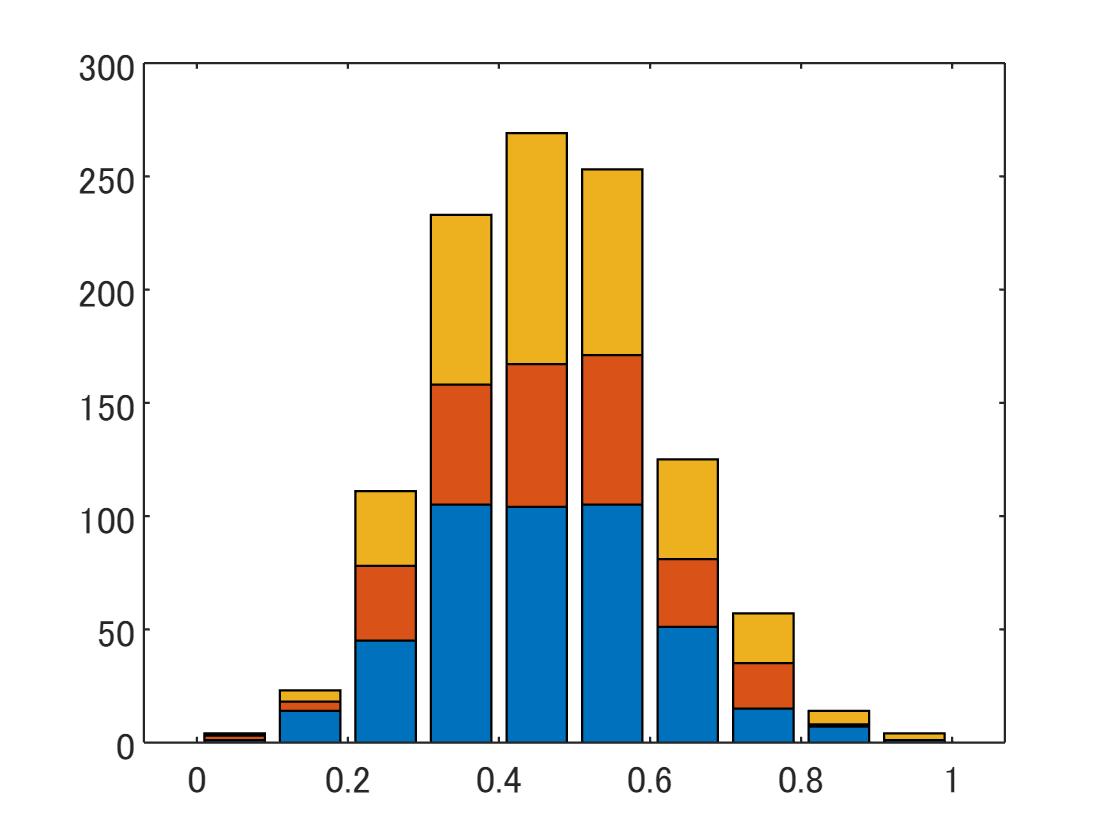

    ind = tbl_results.Year==seasonStartYearVal ...
        & tbl_results.Date>=predictionStartDate;

    PredictedMatches=[PredictedMatches;sum(ind)];
    CorrectsByMassey=[CorrectsByMassey;...

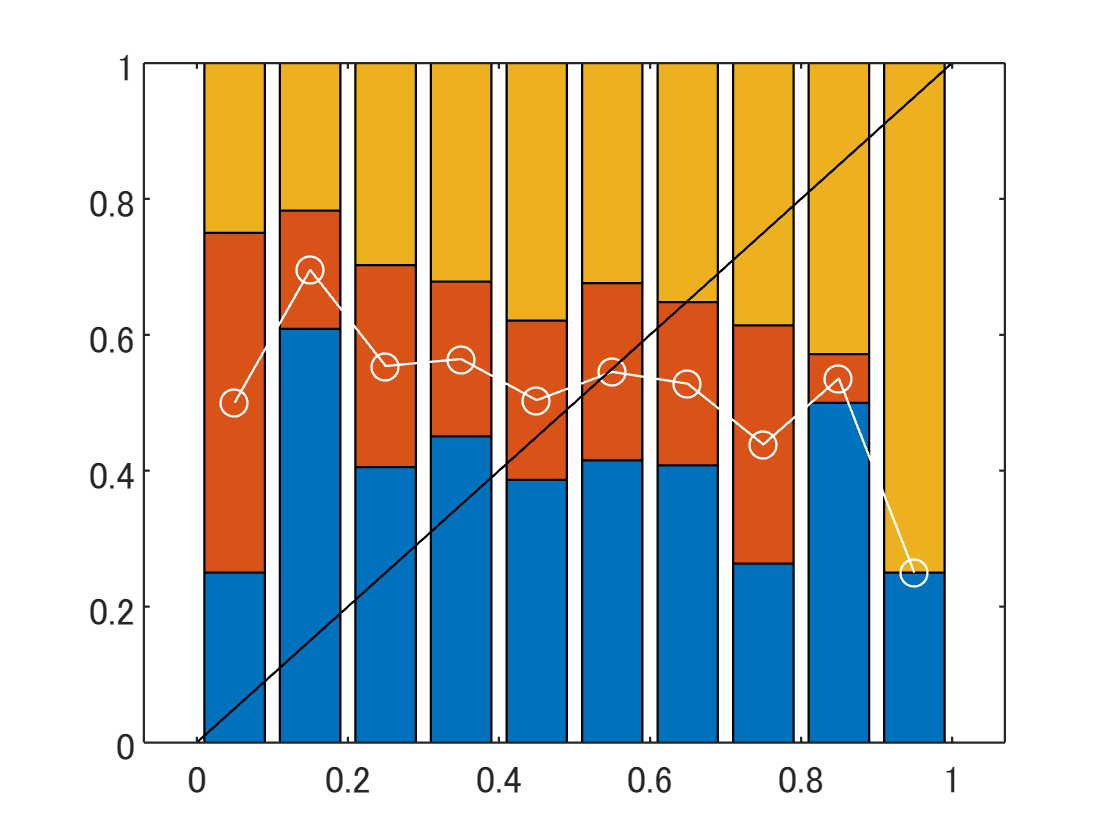

        sum(PredictionByMassey(ind)==ActualWin(ind))];
    PredGoals=[PredGoals;
        RatingValus(ind,1).*RatingValus(ind,4) ...
        RatingValus(ind,3).*RatingValus(ind,2);
        ];
    ActualGoals=[ActualGoals;
        matchData(ind,3) ...

        matchData(ind,4)];
end

図示する

figure;
plot(seasonStartYearVals, CorrectsByMassey./PredictedMatches,'s--');
hold on;grid on;

set(gca,'fontname','メイリオ');
xlabel('年');ylabel('予測正解率');
legend({'Massey+HA+OD'},'Location','best');
title('J1リーグ 予測正解率');
exportgraphics(gcf,'fig_J1PredictionByPairwiseByDate.pdf');

予測得点と実得点

figure;
scatter(PredGoals, ActualGoals);
set(gca,'fontname','メイリオ');
grid on;hold on;
plot([0 4],[0 4],'r--')

bins=0:0.5:4;
hc=[];
for n1=unique(ActualGoals)'
    ind = ActualGoals==n1;
    hc=[hc;histcounts(PredGoals(ind), bins)];
end

(hc'*unique(ActualGoals))./sum(hc)'

predWDL= predByPoisson(PredGoals(:,1), PredGoals(:,2))

ActualWDL=[ ...
    ActualGoals(:,1)>ActualGoals(:,2) ...
    ActualGoals(:,1)==ActualGoals(:,2) ...
    ActualGoals(:,1)<ActualGoals(:,2) ...
]

hc=[];
bins=0:0.1:1;
tmpVal=predWDL(ActualWDL(:,1),1)+predWDL(ActualWDL(:,1),2)/2;
hc=[hc;histcounts(tmpVal,bins)];

tmpVal=predWDL(ActualWDL(:,2),1)+predWDL(ActualWDL(:,2),2)/2;
hc=[hc;histcounts(tmpVal,bins)];

tmpVal=predWDL(ActualWDL(:,3),1)+predWDL(ActualWDL(:,3),2)/2;
hc=[hc;histcounts(tmpVal,bins)];

figure
bar( movmean(bins,2,"Endpoints","discard"), hc, "stacked");
figure
bar( movmean(bins,2,"Endpoints","discard"), ...
    hc./sum(hc), "stacked");
hold on;
plot(movmean(bins,2,"Endpoints","discard"), ...
    (hc(1,:)+hc(2,:)/2)./sum(hc), 'wo-');
plot([0 1],[0 1],'k-')